# DSP Lab 10

## Syed Asghar Abbas Zaidi 07201

#### Task 1


$$\frac{1}{3}\left(x\left\lbrack \left.n-1\right\rbrack +x\left\lbrack n\right\rbrack +x\left\lbrack n+1\right\rbrack \right\rbrack \right)$$


#### **Q1: Why is the above equation called the moving average filter?**

The equation represents a moving average filter because it computes the average of a current sample with its neighboring samples, thus "moving" along the signal.

#### **Q2: Can moving the average filter result in the loss of original data?**

Yes, moving average filters can result in the loss of original data, particularly in cases where the noise being removed is similar in magnitude to the actual signal. The filter smooths out the signal, which can result in a loss of detail, especially in sharp transitions.

#### **Q3: Implement the above equation to remove random noise from a sin signal**

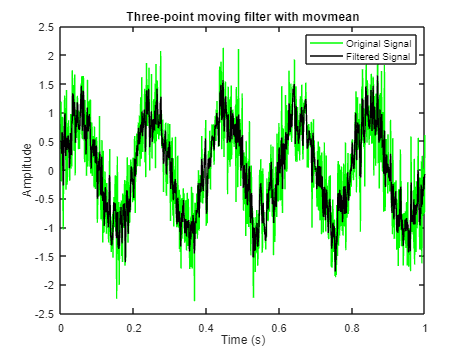

% Generate sine signal with noise
Fs = 1000;                % Sampling frequency
t = 0:1/Fs:1;             % Time vector
f = 5;                    % Frequency of sine wave
x = sin(2*pi*f*t) + 0.5*randn(size(t));  % Sine wave with noise

% Implement moving average filter
filtered_signal = movmean(x, 3);  % 3-point moving average filter

% Plot original and filtered signals
figure;
plot(t, x, 'g', t, filtered_signal, 'k');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal', 'Filtered Signal');
title('Three-point moving filter with movmean');

#### **Q4: You can use the built-in MATLAB filter command filter(num,den,x). Q6 attach the results. Q7 attaching the zero-pole diagram.**

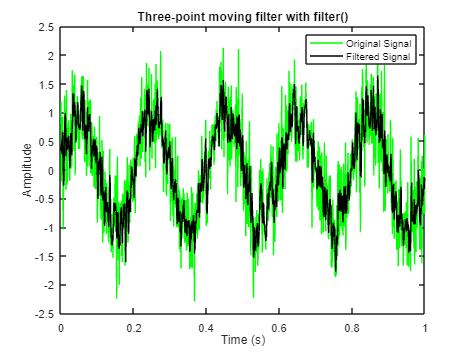

% Implement moving average filter using filter command
num = [1, 1, 1]/3;    % Coefficients for moving average filter
den = 1;                  % No denominator for moving average (FIR) filter
filtered_signal = filter(num, den, x);

% Plot original and filtered signals
figure;
plot(t, x, 'g', t, filtered_signal, 'k');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal', 'Filtered Signal');
title('Three-point moving filter with filter()');

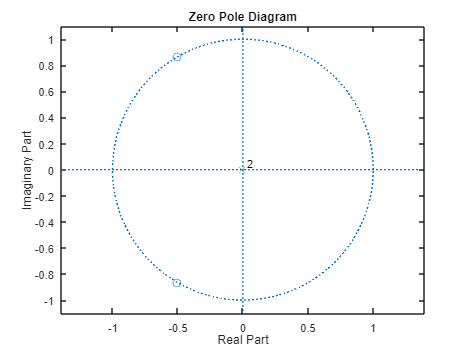


% Plot zeros (there are no poles for FIR filters)
figure;
zplane(num, den);
title('Zero Pole Diagram');

#### **Q5: Describe how have you chosen the values of num and den**

`"num"` contains the numerator coefficients of the filter, which represent the moving average window. Since it's a simple averaging, we have used `[1, 1, 1] / 3`, which corresponds to a 3-point moving average filter.

`"den"` contains the denominator coefficients, which are 1 for FIR filters.

We then use the `"filter"` function to apply the filter to the noisy signal `x`, resulting in the "`filtered_signal"`.

#### **Q8: Instead of a three point moving average filter, create a 5 point average filter. Were the results better in terms of removing noise?**

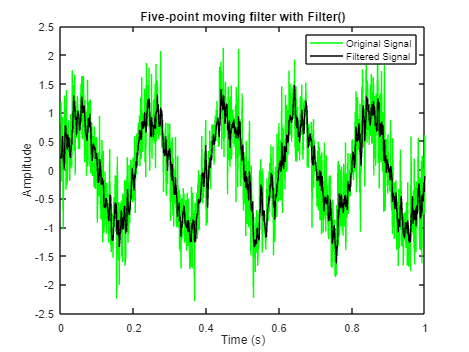

% Implement moving average filter using filter command
num = [1, 1, 1, 1, 1]/5;    % Coefficients for moving average filter
den = 1;                  % No denominator for moving average (FIR) filter
filtered_signal = filter(num, den, x);

% Plot original and filtered signals
figure;
plot(t, x, 'g', t, filtered_signal, 'k');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Original Signal', 'Filtered Signal');
title('Five-point moving filter with Filter()');

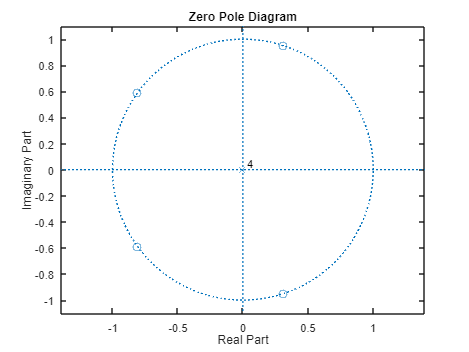


% Plot zeros (there are no poles for FIR filters)
figure;
zplane(num, den);
%pzmap(num, den);
title('Zero Pole Diagram');

#### Q9: Compare the zero pole diagram of both filters 

We are observing that there are zeros to be found in three-point filter on the negative real side only. From this, we can infer that we are forming a low-pass filter. 

In the five-point filter however, we can observe zeros being formed at the negative as well as positive side, from this we can infer that band-pass filter is being formed cause it is exhibiting the properties of both low-pass as well as high-pass! 

**Further explanation:**

**Low-Pass Filter**: The three-point filter, with its zeros on the negative real side, emphasizes the removal of high-frequency noise or rapid fluctuations.It’s like allowing a smooth signal (low-frequency components) to pass through while filtering out the noise.

**Band-Pass Filter**: The five-point filter, with zeros on both sides, exhibits a broader behavior. It allows a specific range of frequencies (the “band”) to pass through. This could be useful for extracting specific features or analyzing signals within a certain frequency range.

#### Q10. A data matrix S has been provided to you. The data was believed to have pure tone signal. However the received data has noise added to it. Can you help to provide the original signal. Here is some additional information look for fft command 

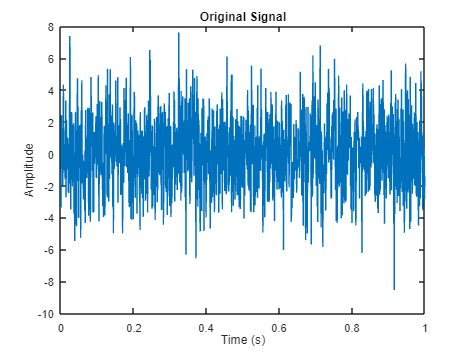

% Load the data from the matrix.mat file
X = load('Matrix.mat');
X = X.X;
L = 1500;
t= linspace(min(t), max(t), length(X));
% Plot the original signal
figure;
plot(t, X);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Signal');

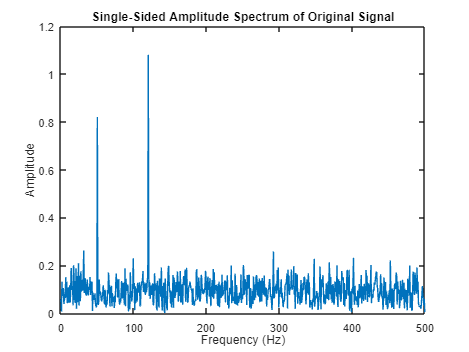


% Perform FFT to analyze frequency components
Y = fft(X);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

% Plot the single-sided amplitude spectrum
figure;
plot(f, P1);
xlabel('Frequency (Hz)');
ylabel('Amplitude');
title('Single-Sided Amplitude Spectrum of Original Signal');

As can be observed, there are two siginificant frequencies, one is 50Hz and another is 120Hz. So to remove the noise aside of two frequencies that I want to acquire, I will be using two bandpass filters to remove them. I will later combine the results from both of the filters to reconstruct the signal. 

#### Filter Design, Band-pass for 50Hz frequency

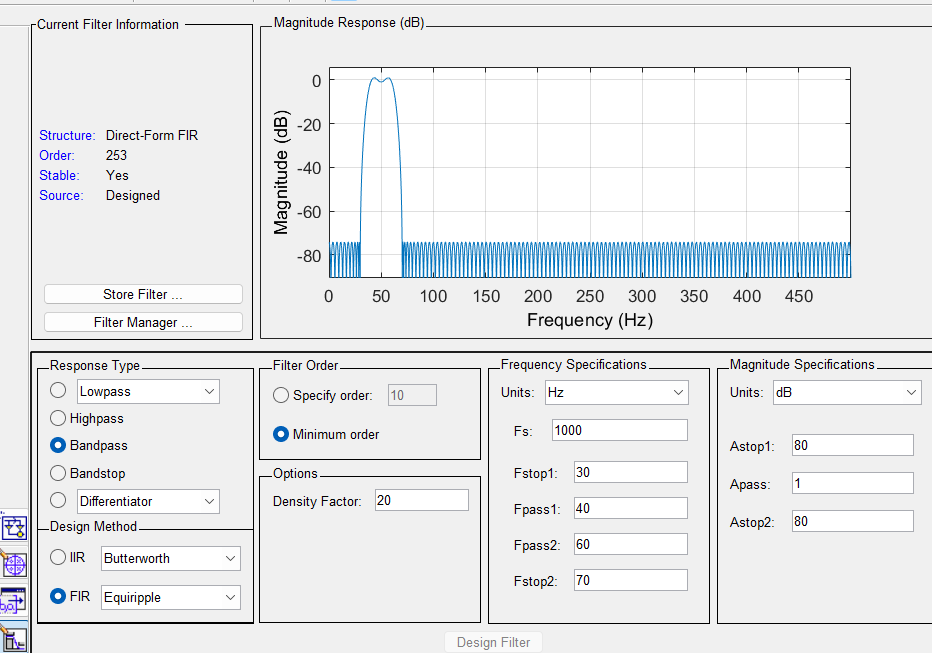

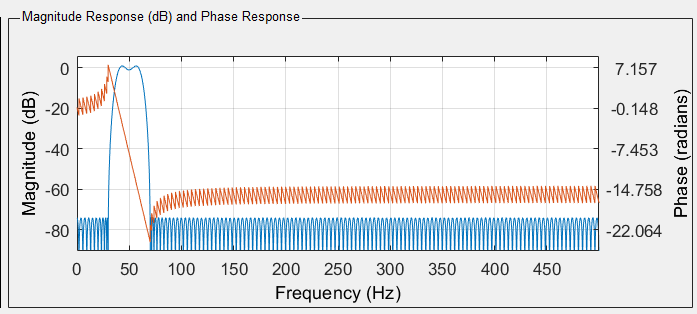

#### Filter Design, Band-pass for 120Hz frequency

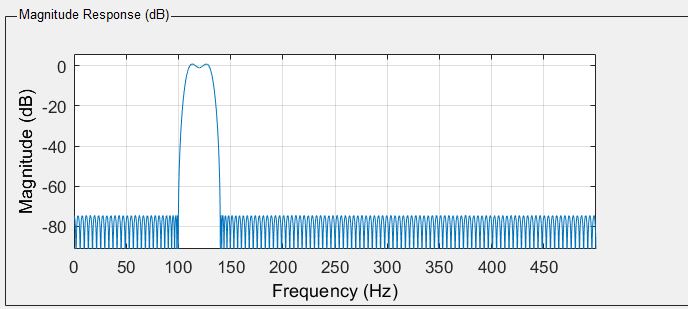

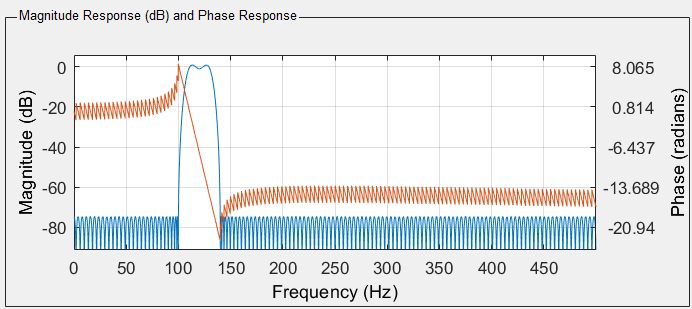

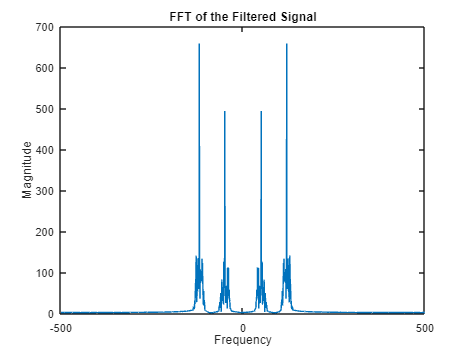

 filter50 = load('Bandpass1.mat');
 filter50 = filter50.BandPass1;
 filter120 = load('Bandpass2.mat');
 filter120 = filter120.BandPass2;
 d1 = filter(filter50,1,X);
 d2 = filter(filter120,1,X);
 d = d1 + d2;
 d_fft = fftshift(fft(d));
 N2 = length(d);
 f_axis_2 = linspace(-Fs/2, Fs/2, N2);
 plot(f_axis_2,abs(d_fft));
 title("FFT of the Filtered Signal")
 xlabel("Frequency")
 ylabel("Magnitude")    

We have successfully gotten rid of the noise pretty significantly.

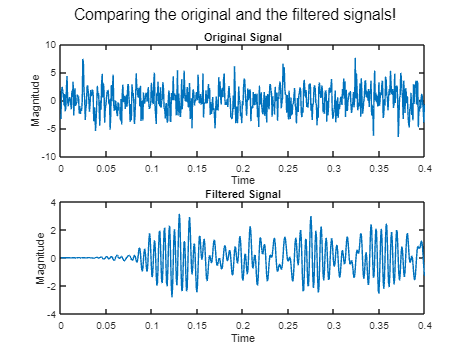

clf;
 subplot(2,1,1)
 plot(t,X);
 title("Original Signal")
 xlabel("Time")
 ylabel("Magnitude")
 xlim([0 0.4]);
 subplot(2,1,2)
 plot(t,d);
 title("Filtered Signal")
 xlabel("Time")
 ylabel("Magnitude")
  xlim([0 0.4]);
 sgtitle("Comparing the original and the filtered signals!")

#### **Q11. A  image is given with name of man.png. Use fft2 command to remove filters from this image (Optional) **

I implemented a low-pass filter as was asked of me, however, the image still didn't get better. We were later told that this question is optional

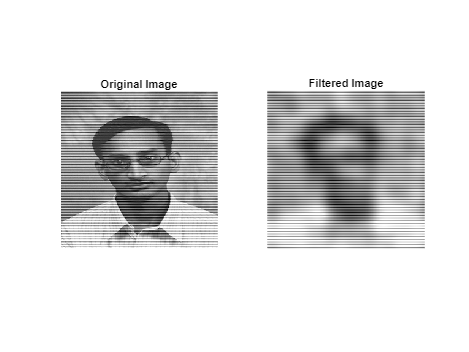

image_data = imread('man.png');

% Perform FFT on the image
image_fft = fft2(double(image_data));

% Manipulate frequency components (e.g., remove high-frequency noise)
% Example: set high-frequency components to zero
threshold = 100000; % Adjust as needed
image_fft(abs(image_fft) < threshold) = 0;

% Perform inverse FFT to get the filtered image
filtered_image = ifft2(image_fft);

% Display the original and filtered images
figure;
subplot(1, 2, 1);
imshow(image_data);
title('Original Image');

subplot(1, 2, 2);
imshow(uint8(abs(filtered_image)));
title('Filtered Image');

### **Creating Blur Animation on Images Using Moving Average Filter **

An animation is a simple sequence of various frames, that are played in a particular order. The following task consists of two sub-tasks. The first part deals, with creating a blurred image, and the second part uses a loop to increase the value of blur in order to create a blur animation

#### Q1: Take an image from the internet and load it into matlab 

image_data = imread('Bloodborne_art.jpg');

#### Q2: Apply Moving average filter using fspecial('average',[10,10]); Q4 Showing the result as well

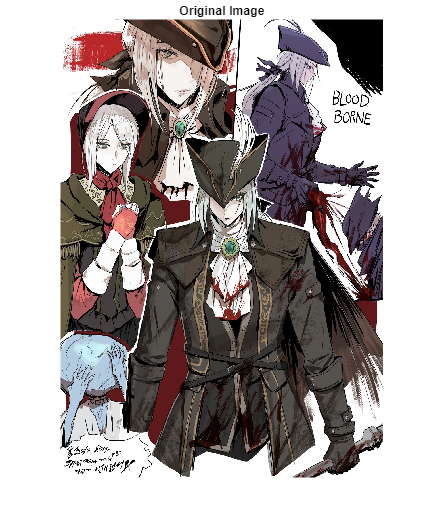

% Display the original image
figure;
imshow(image_data);
title('Original Image');

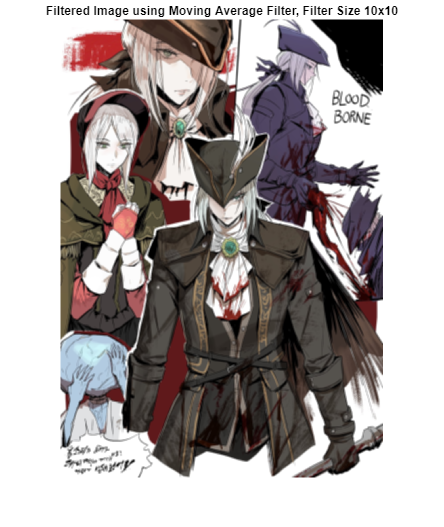


% Apply the moving average filter
moving_avg_filter = fspecial('average', [10, 10]);
filtered_image = imfilter(image_data, moving_avg_filter, 'replicate');

% Display the filtered image
figure;
imshow(filtered_image);
title('Filtered Image using Moving Average Filter, Filter Size 10x10');

#### Q3: What does 10 by 10 represents 

The [10, 10] in `fspecial('average', [10, 10])` means that  we're creating a special filter called "average" that will be used to  blur the image. The [10, 10] part specifies the size of this filter.  It's like a window that moves over the image, and at each position, it  looks at a 10x10 square of pixels. It then calculates the average (or  mean) value of all the pixels in that square. This averaging process  helps to smooth out the image and make it look blurry. So, basically,  the [10, 10] tells us how big the window is for blurring the image.

#### Q5: Now use a loop on average filter and represent your result (choose a big loop value)

Following creates a video where various filter sizes are used one by one.

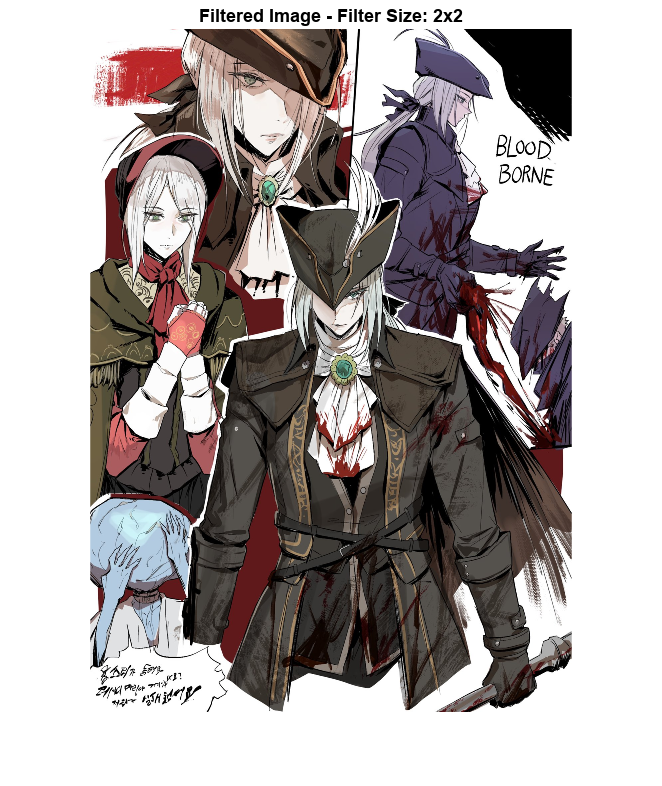

% Load the original image
original_image = imread('Bloodborne_art.jpg');


% Set filter sizes to iterate through
filter_sizes = [2,2; 3, 3; 4,4; 5, 5; 6,6; 7,7; 8,8; 9,9; 10,10; ...
    11,11; 12,12; 13,13; 14,14; 15,15; 16,16; 17,17; 18,18; 19,19; 20,20;...
    21,21; 22,22; 23,23; 24,24; 25,25; 26,26; 27,27; 28,28; 29,29; 30,30;];  % Example: You can add more sizes

% Prepare video writer
frames_per_second = 5;  % Adjust as needed
v = VideoWriter('filter_effects.avi');
open(v);

% Iterate through filter sizes
for i = 1:size(filter_sizes, 1)
    filter_size = filter_sizes(i, :);
    
    % Apply the filter
    filtered_image = imfilter(original_image, fspecial('average', filter_size), 'replicate');
    
    % Display and write frame to video
    figure;
    imshow(filtered_image);
    title(sprintf('Filtered Image - Filter Size: %dx%d', filter_size(1), filter_size(2)));
    frame = getframe(gcf);
    writeVideo(v, frame);
    writeVideo(v, frame);
    writeVideo(v, frame);
    close;
end


% Close video writer
close(v);


As the pdf itself won't contain the video, showcasing 30x30 moving filter result as well

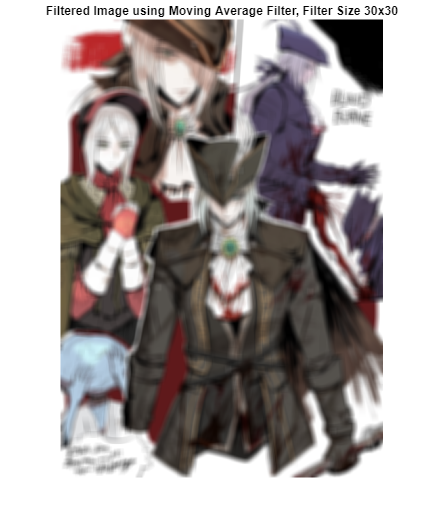

% Apply the moving average filter
moving_avg_filter = fspecial('average', [30, 30]);
filtered_image = imfilter(image_data, moving_avg_filter, 'replicate');

% Display the filtered image
figure;
imshow(filtered_image);
title('Filtered Image using Moving Average Filter, Filter Size 30x30');

## SOUNDS!

#### Part a, b and c)

 % Define frequencies of each note
 frequencies = [262, 294, 330, 349, 392, 440, 494]; % Frequencies in Hz
 % Define the sequence of notes to play
 sequence = ['C', 'D', 'E', 'F', 'G', 'A', 'B']; % Index of notes in the frequencies array
 % Duration of each note (in seconds)
 note_duration = 0.5;
 % Sampling frequency
 fs = 44100;
 % Initialize the sequence of sound samples
 sound_sequence = ['C','C','G','G','A','A','G','F','F','E','E','D',...
    'D','C','G','G','F','F','E','E','D','G','G','F','F','E','E',...
    'D','C','C','G','G','A','A','G','F','F','E','E','D','D','C'];
 signal = [];
 for i = 1:length(sound_sequence)
    % find the index
    index = find(sequence == sound_sequence(i));
    % generate the corresponding sine wave
    t = 0:1/fs:note_duration;
    note_signal = sin(2*pi*frequencies(index)*t);
    % Append the note signal to the music signal
    signal = [signal, note_signal];
 end
 % play the generated music
 sound(signal, fs);
 audiowrite('tune.wav', signal, fs);
 

**Explanation of the above code: **

The provided MATLAB code is designed to generate a sequence of musical notes and play them. It first defines the frequencies of each note in Hertz, and then sets up a sequence of notes to play. The duration of each note is set to 0.5 seconds and the sampling frequency is set to 44100 Hz. The code then initializes a sequence of sound samples, which is a string of characters representing the notes to be played. For each character in this sequence, the code finds the corresponding frequency, generates a sine wave for the duration of the note at that frequency, and appends this to the signal. Once all the notes have been processed, the resulting signal, which is a concatenation of all the individual note signals, is played. Additionally, the signal is written to a .wav file named ‘tune.wav’

#### d)

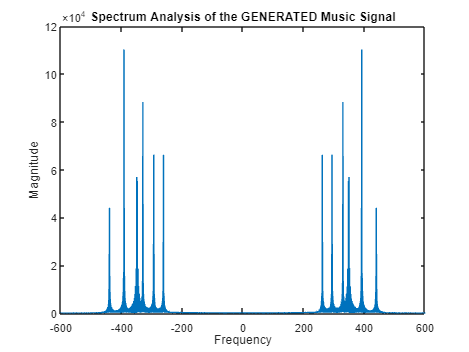

 % Perform FFT on the music signal
 music_spectrum = fftshift(fft(signal));
 % Calculate the frequency axis
 freq_axis = (-length(music_spectrum)/2:length(music_spectrum)/2-1) * (fs / length(music_spectrum));
 % Plot the spectrum
 figure;
 plot(freq_axis, abs(music_spectrum));
 xlim([-600 600])
 xlabel('Frequency');
 ylabel('Magnitude');
 title('Spectrum Analysis of the GENERATED Music Signal');

#### Explanation of the above code:

In this MATLAB code, we delve into the spectrum analysis of a music signal. Initially, we apply the Fast Fourier Transform (FFT) to the music signal, shifting the zero-frequency component to the spectrum's center. The resulting transformed signal, stored in the variable music_spectrum, undergoes further processing. We calculate the frequency axis freq_axis, taking into account the length of the music spectrum and the sampling frequency fs. Subsequently, we plot the absolute values of the music spectrum against the frequency axis, focusing the x-axis on the range of -600 to 600 Hz. This plot, labeled with 'Frequency (Hz)' on the x-axis, 'Magnitude' on the y-axis, and titled 'Spectrum Analysis of Generated Music Signal,' offers a compelling visual insight into the frequency components inherent in the music signal.

**In this FFT, every frequency is visible except for the 494Hz frequency corresponding to the 'B' note.**

#### e)

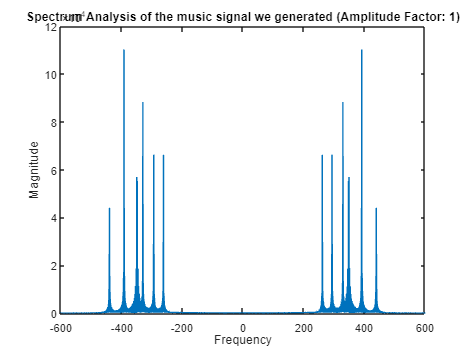

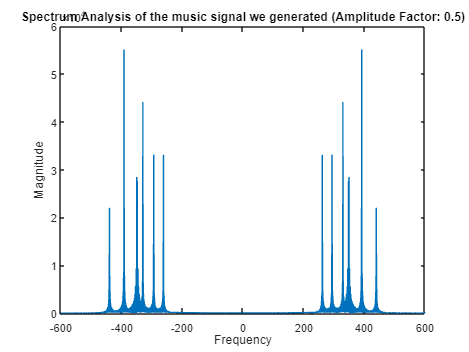

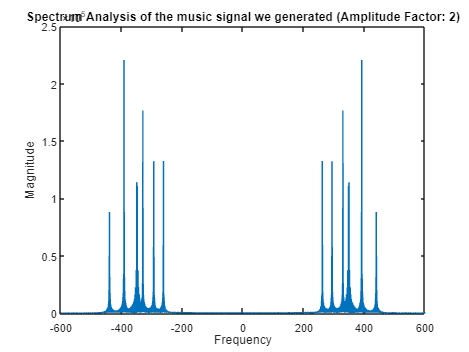

  % Define frequencies of each note
 frequencies = [262, 294, 330, 349, 392, 440, 494]; % Frequencies in Hz
 % Define the sequence of notes to play
 sequence = ['C', 'D', 'E', 'F', 'G', 'A', 'B']; % Index of notes in the frequencies array
 % Duration of each note (in seconds)
 note_duration = 0.5;
 % Sampling frequency
 fs = 44100;
 % Initialize the sequence of sound samples
 sound_sequence = ['C','C','G','G','A','A','G','F','F','E','E','D',...
    'D','C','G','G','F','F','E','E','D','G','G','F','F','E','E',...
    'D','C','C','G','G','A','A','G','F','F','E','E','D','D','C'];
 % Initialize arrays to store results
 spectra = cell(3, 1); % For storing spectra
 amplitudes = [1, 0.5, 2]; % Amplitude factors to test
 % Generate spectra for different amplitudes
 for a = 1:length(amplitudes)
    amplitude_factor = amplitudes(a);
    signal = []; % Reset signal for each iteration
 for i = 1:length(sound_sequence)
 % find the index
        index = find(sequence == sound_sequence(i));
 % generate the corresponding sine wave with adjusted amplitude
        t = 0:1/fs:note_duration;
        note_signal = amplitude_factor * sin(2*pi*frequencies(index)*t);
 % Append the note signal to the music signal
        signal = [signal, note_signal];
 end
 % Perform FFT on the music signal
    music_spectrum = fftshift(fft(signal));
 % Calculate the frequency axis
    freq_axis = (-length(music_spectrum)/2:length(music_spectrum)/2-1) * (fs / length(music_spectrum));
 % Store the spectrum
    spectra{a} = abs(music_spectrum);
 % Plot the spectrum for this amplitude
    figure;
    plot(freq_axis, spectra{a});
    xlim([-600 600])
    xlabel('Frequency');
    ylabel('Magnitude');
    title(['Spectrum Analysis of the music signal we generated (Amplitude Factor: ', num2str(amplitude_factor), ')']);
 end

#### Explanation of the code:

The provided MATLAB code generates a sequence of musical notes, performs a spectrum analysis on the generated music signal, and plots the spectrum for different amplitude factors. It first defines the frequencies of each note in Hertz and the sequence of notes to play. The duration of each note is set to 0.5 seconds and the sampling frequency is set to 44100 Hz. The code then initializes the sequence of sound samples and arrays to store the results. For each amplitude factor in the array [1, 0.5, 2], it generates the corresponding sine wave for each note in the sound sequence with the adjusted amplitude and appends it to the music signal. After generating the music signal, it performs a Fast Fourier Transform (FFT) on the signal, shifts the zero-frequency component to the center of the spectrum, and calculates the frequency axis. The absolute value of the music spectrum is stored and plotted against the frequency axis, with the x-axis limited to the range of -600 to 600 Hz. 

**And yes, altering the amplitude of a signal has a discernible impact on its Fourier spectrum. **When the amplitude of a signal is heightened, it results in an augmentation of the amplitudes associated with its respective frequency components within the Fourier spectrum. Conversely, reducing the amplitude of the signal leads to a diminution in the amplitudes of these components. This relationship underscores the fundamental principle that changes in signal amplitude directly influence the distribution and magnitude of frequency components, highlighting the intricate interplay between amplitude modulation and spectral characteristics in signal processing.

#### f)

When you increase the amplitude of all frequencies in a signal, it leads to an overall enhancement in the magnitude of the Fourier spectrum.  This change affects all frequency components equally, resulting in a  scaled version of the original spectrum. Mathematically, if you have a  signal (x(t)) with Fourier transform (X(f)), and you multiply the signal by a constant (A), the Fourier transform of the scaled signal (Ax(t))  will be (AX(f)). In simpler terms, each frequency component in the  spectrum will be multiplied by the same constant (A). Graphically, this  means that all peaks in the Fourier spectrum will be scaled up by the  same factor when you increase the amplitude of all frequencies in the  signal. Conversely, decreasing the amplitudes of all frequencies would  result in a scaled-down version of the spectrum. Furthermore, this  change in amplitude directly impacts the perceived loudness of the tune.

#### g)

When altering the sampling frequency, significant implications arise for signal characteristics and the Fourier spectrum. Decreasing the sampling frequency results in the loss of high-frequency information, leading to a diminished ability to accurately represent rapid changes in the signal and potentially affecting subsequent analyses. Additionally, a lower sampling frequency reduces frequency resolution, making it harder to distinguish closely spaced frequencies within the spectrum. Furthermore, undersampling can lead to aliasing, where high-frequency components fold into lower frequency ranges, causing distortion and misinterpretation of the signal. Conversely, increasing the sampling frequency offers benefits such as enhanced frequency resolution, allowing for finer discrimination between adjacent frequencies and better identification of spectral components. Moreover, a higher sampling frequency helps prevent aliasing and accurately captures high-frequency details, ensuring a more faithful representation of the original signal in the Fourier spectrum. This underscores the critical role of selecting an appropriate sampling frequency to balance information preservation and computational efficiency in signal processing applications.

#### h)

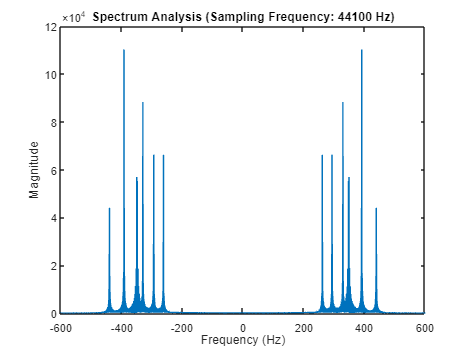

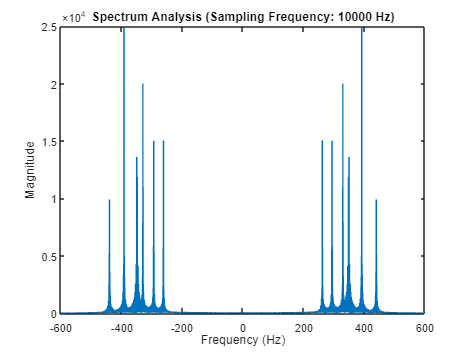

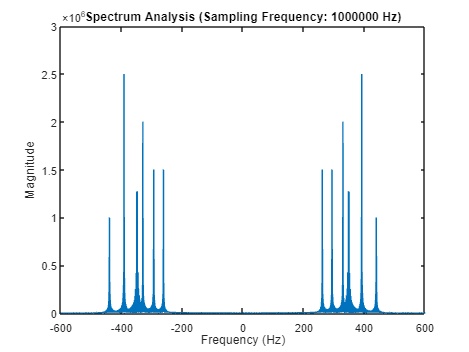

 % Define frequencies of each note
 frequencies = [262, 294, 330, 349, 392, 440, 494]; % Frequencies in Hz
 % Define the sequence of notes to play
 sequence = ['C', 'D', 'E', 'F', 'G', 'A', 'B']; % Index of notes in the frequencies array
 % Duration of each note (in seconds)
 note_duration = 0.5;
 % Initialize the sequence of sound samples
 sound_sequence = ['C','C','G','G','A','A','G','F','F','E','E','D',...
 'D','C','G','G','F','F','E','E','D','G','G','F','F','E','E',...
 'D','C','C','G','G','A','A','G','F','F','E','E','D','D','C'];
 % Initialize arrays to store results
 spectra = cell(3, 1); % For storing spectra
 sampling_freqs = [44100, 10000, 1000000]; % Sampling frequencies to test
 % Generate spectra for different sampling frequencies
 for f = 1:length(sampling_freqs)
    fs = sampling_freqs(f);
    signal = []; % Reset signal for each iteration
 for i = 1:length(sound_sequence)
 % find the index
        index = find(sequence == sound_sequence(i));
 % generate the corresponding sine wave
        t = 0:1/fs:note_duration;
        note_signal = sin(2*pi*frequencies(index)*t);
 % Append the note signal to the music signal
        signal = [signal, note_signal];
 end
 % Perform FFT on the music signal
    music_spectrum = fftshift(fft(signal));
 % Calculate the frequency axis
    freq_axis = (-length(music_spectrum)/2:length(music_spectrum)/2-1) * (fs / length(music_spectrum));
 % Store the spectrum
    spectra{f} = abs(music_spectrum);
 % Plot the spectrum for this sampling frequency
    figure;
    plot(freq_axis, spectra{f});
    xlim([-600 600])
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');
   title(['Spectrum Analysis (Sampling Frequency: ', num2str(fs), ' Hz)']);
 end

The modification of sampling frequency primarily influences the amplitude of the frequency spectrum without introducing or eliminating frequency components within the spectrum. Adjusting the sampling frequency alters the spacing between frequency bins in the spectrum, affecting how the amplitude of each frequency component is represented. However, it does not change the fundamental frequencies present in the signal. Consequently, increasing or decreasing the sampling frequency results in a scaling effect on the amplitude axis of the spectrum, impacting the magnitude of each frequency component while maintaining the same set of frequencies. 

## Correlations examples

  % Load the images
 image1 = imread('fig1.png'); % Figure 1
 image2 = imread('fig2.png'); % Figure 2
 % Convert the images to grayscale if needed
 if size(image1, 3) > 1
    image1 = rgb2gray(image1);
 end
 if size(image2, 3) > 1
    image2 = rgb2gray(image2);
 end
 % Calculate the cross-correlation between the images
 correlation = normxcorr2(image2, image1);
 

### Setting the Threshold = 0.99

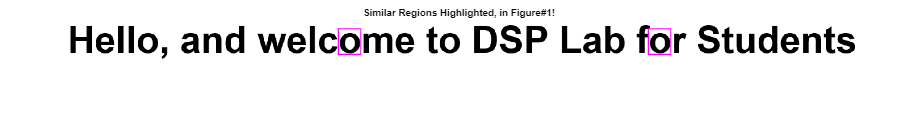

  % SETTING THE CORRELATION THRESHOLD (ADJUST HOWEVER YOU LIKE)
 threshold = 0.99;
 % FIND LOCATIONS WHERE IT EXCEEDS THRESHOLD
 [row, col] = find(correlation > threshold);
 % Highlight the regions of similarity in the original image with rectangles
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 title('Similar Regions Highlighted, in Figure#1!');
 hold off;

### Setting the Threshold = 0.9

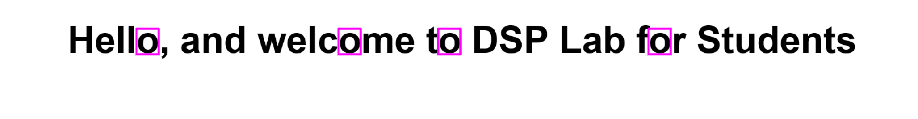

 threshold = 0.9;
 [row, col] = find(correlation > threshold);
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 hold off;

### Setting the Threshold = 0.8

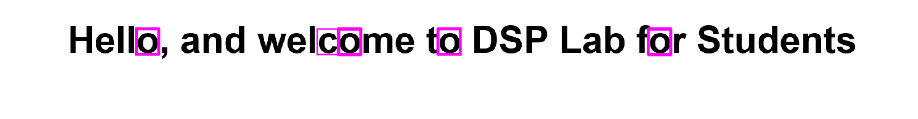

 threshold = 0.8;
 [row, col] = find(correlation > threshold);
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 hold off;

###  Setting the Threshold = 0.7

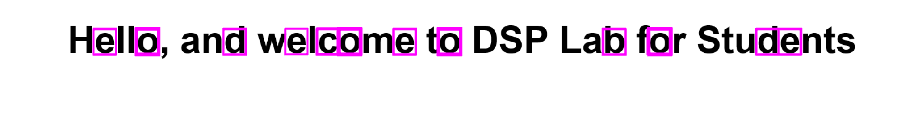

% Set a correlation threshold (adjust as needed)
 threshold = 0.70;
 % Find the locations where the correlation exceeds the threshold
 [row, col] = find(correlation > threshold);
 % Highlight the regions of similarity in the original image (Figure 2) with rectangles
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 hold off;

### Setting the  Threshold = 0.60

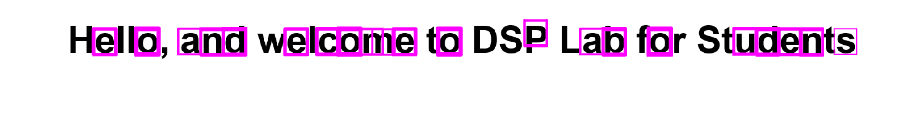

% Set a correlation threshold (adjust as needed)
 threshold = 0.60;
 % Find the locations where the correlation exceeds the threshold
 [row, col] = find(correlation > threshold);
 % Highlight the regions of similarity in the original image (Figure 2) with rectangles
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 hold off;

### Setting the Threshold = 0.50

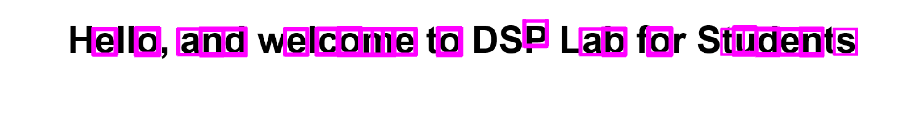

% Set a correlation threshold (adjust as needed)
 threshold = 0.50;
 % Find the locations where the correlation exceeds the threshold
 [row, col] = find(correlation > threshold);
 % Highlight the regions of similarity in the original image (Figure 2) with rectangles
 figure;
 imshow(image1);
 hold on;
 for i = 1:length(row)
    rectangle('Position', [col(i)-size(image2, 2), row(i)-size(image2, 1), size(image2, 2), size(image2, 1)], 'EdgeColor', 'm', 'LineWidth', 1);
 end
 hold off;

## ANALYSIS!!

When the threshold is set high at 0.9, we observe accurate detection of "Os." However, as we progressively lower the threshold below this value, the number of false positives increases. It's worth noting that when the threshold is excessively high like 0.99, we encounter false negatives, where images actually exist but remain undetected. Therefore, finding the optimal threshold involves balancing the trade-off between false positives and false negatives. In this scenario, the threshold of 0.9 appears to strike a suitable balance, resulting in accurate detection while minimizing false positives and false negatives.

### **Explanation of how the code works! THE OVERALL EXPLANATION!!**

The process begins by converting both images into **grayscale**, reducing them to a single channel. 

**Grayscale** conversion simplifies the images by representing each pixel's intensity or brightness rather than its color, making them easier to process and compare. Next, the **normxcorr2**() function is employed to calculate the correlation between the grayscale images. **normxcorr2() computes the normalized cross-correlation, generating a correlation map that highlights areas of similarity between the images**. Depending on the set similarity threshold, x and y coordinates are extracted from the correlation map. The similarity threshold defines the minimum correlation coefficient required for a region to be considered a match. 

**Higher thresholds result in stricter criteria for similarity, while lower thresholds allow for more leniency**. 

Subsequently,** rectangles are superimposed on the images to pinpoint regions of similarity with the template image (Figure 2).** Initially, with a threshold of 0.99 with lead to false negatives. However, as the threshold decreases, more similarities emerge. For instance, lowering the threshold to 0.90 reveals additional similarities. It's important to note that excessively high thresholds may result in false negatives, where existing images remain undetected. Conversely, decreasing the threshold beyond a certain point increases the likelihood of false positives like what we could see when we decreased it to 0.80. 

The process of adjusting the threshold continues until an optimal value is reached. In this case, a threshold of 0.9 is deemed optimal, successfully identifying all actual similarities without introducing any false positives. Fine-tuning the similarity threshold is crucial to strike a balance between sensitivity and specificity, ensuring accurate detection of similarities between images.